# **TP Computer Vision : Events cameras**

**Done by: **

- **AMMAR KHODJA Rayane 20225452**

- **Daniel Shehroz khan SABIR JAMIL 20235553**

## **Introduction:**

`Visual flow estimation is an active research area with applications in artificial vision and navigation. However, estimating dense flow fields on natural scenes in real-time remains challenging. Popular techniques can be categorized as energy-based, phase-based, correlation-based, or differential methods. While correlation-based methods perform well for stereo matching, differential methods are better suited for optical flow estimation. However, accuracy of differential techniques comes at the cost of computational complexity. Larger convolution kernels and temporal buffers improve accuracy but dramatically increase processing time, making real-time performance difficult. Thus, a trade-off exists between accuracy and efficiency. Recent work has focused on speeding up flow computation through parallelization and algorithmic improvements while retaining sufficient accuracy. However, additional progress is needed to achieve dense, precise flow estimation at high frame rates. This report surveys common visual flow techniques and recent advances in efficient and accurate flow estimation.`

## `Theoritical part:`

`Check the pdf file attached to this repport.`

## Practical Work:

- shapes_translation data:

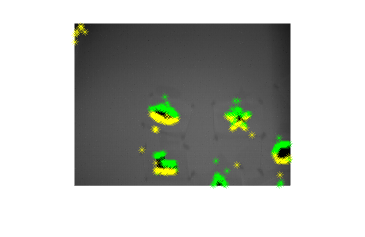

% Load event data from events.txt
eventsData = load('shapes_translation/events.txt');
eventTimestamps = eventsData(:, 1);
eventX = eventsData(:, 2);
eventY = eventsData(:, 3);
eventPolarity = eventsData(:, 4);

% Load image data from images.txt
imagesData = importdata('shapes_translation/images.txt');
imageTimestamps = cellfun(@(x) str2double(regexp(x, '(\d+\.\d+)', 'match', 'once')), imagesData);
imageFilenames = cellfun(@(x) regexp(x, '\s(.+)', 'tokens', 'once'), imagesData, 'UniformOutput', false);

% Load frame images
imageFolderPath = 'shapes_translation/';
frameImages = cell(length(imageFilenames), 1);

for i = 1:length(imageFilenames)
    imagePath = fullfile(imageFolderPath, imageFilenames{i}{1});
    frameImages{i} = imread(imagePath);
end


temporalWindow = 0.001; 

figure;
% Display frames and events
for i = 1:length(imageTimestamps)
    frameTimestamp = imageTimestamps(i);
    
    % Find events within the temporal window around the frame
    relevantEvents = find(abs(eventTimestamps - frameTimestamp) <= temporalWindow);
    
    % Plot the frame
    
    imshow(frameImages{i});
    
    hold on;
    
    % Plot events with positive polarity in red and negative in blue
    for j = 1:length(relevantEvents)
        eventTimestamp = eventTimestamps(relevantEvents(j));
        eventXPos = eventX(relevantEvents(j));
        eventYPos = eventY(relevantEvents(j));
        eventPolarityVal = eventPolarity(relevantEvents(j));
        
        if eventPolarityVal == 1
            plot(eventXPos, eventYPos, 'g*');  % Positive events in red
        else
            plot(eventXPos, eventYPos, 'y*');  % Negative events in blue
        end
    end
    pause(0.1);
    hold off;
    
    title(['Frame ' num2str(i)]);
    xlabel('X Position');
    ylabel('Y Position');
end

legend('Positive events (green)', 'Negative events (yellow)');